% Load Times -- PICK ONE -- 
%npru
%time = readcell(strcat("C:\Users\CamilaFonseca\Documents\GitHub\AED\A03\results_npru\times"));
%pru
%time = readcell(strcat("C:\Users\CamilaFonseca\Documents\GitHub\AED\A03\results_pru\results\times"));
%opt
%time = readcell(strcat("C:\Users\CamilaFonseca\Documents\GitHub\AED\A03\results_opt\times"));
%times = [str2double(string(time(:,1))),str2double(regexprep(regexprep(time(:,4),',',"."),'s',""))];

% Load Results -- PICK THE SAME AS BEFORE -- 
numSym=length(times);
results = zeros(numSym-2,9);
%       number of calls per message symbol      lookahead symbols
%      -----------------------------------  ---------------------
%  ns       min      avg      med      max   min    avg  med  max
% ---  -------- -------- -------- --------  ---- ------ ---- ----

for i = 3:numSym
    %npru
    %results(i-2,:) = load(strcat("C:\Users\CamilaFonseca\Documents\GitHub\AED\A03\results_npru\",sprintf('%04.0f', i))); 
    %pru
    %results(i-2,:) = load(strcat("C:\Users\CamilaFonseca\Documents\GitHub\AED\A03\results_pru\results\",sprintf('%04.0f', i)));
    %opt
    %results(i-2,:) = load(strcat("C:\Users\CamilaFonseca\Documents\GitHub\AED\A03\results_opt\",sprintf('%04.0f', i)));    
end

% Load Max Possibilities
maxp = zeros(97,1);
for i = 3:100
    maxp(i-2) = load(strcat("./results_mod/",sprintf('%04.0f', i))); 
end

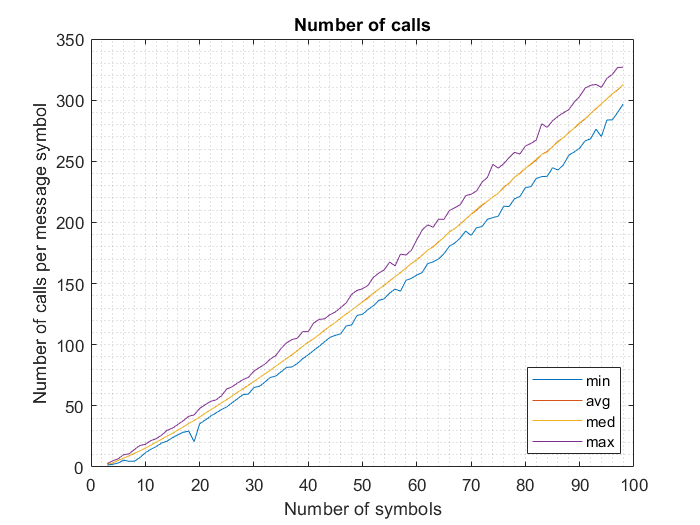

% Plot Number of Calls
for k= 1:4
    plot(results(:,1),results(:,1+k));
    hold on;
end
hold off;
legend("min","avg","med","max","Location","southeast");
title("Number of calls");
xlabel("Number of symbols");
ylabel("Number of calls per message symbol");
grid("minor");
%saveas(gcf,"number_of_calls.png"); 

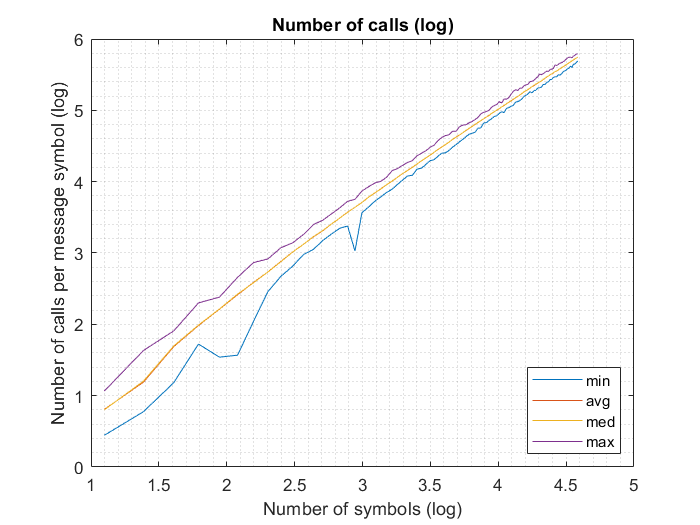

% Plot Number of Calls (log)
for k= 1:4
    plot(log(results(:,1)),log(results(:,1+k)));
    hold on;
end
hold off;
legend("min","avg","med","max","Location","southeast");
title("Number of calls (log)");
xlabel("Number of symbols (log)");
ylabel("Number of calls per message symbol (log)");
grid("minor");
%saveas(gcf,"number_of_calls_log.png"); 

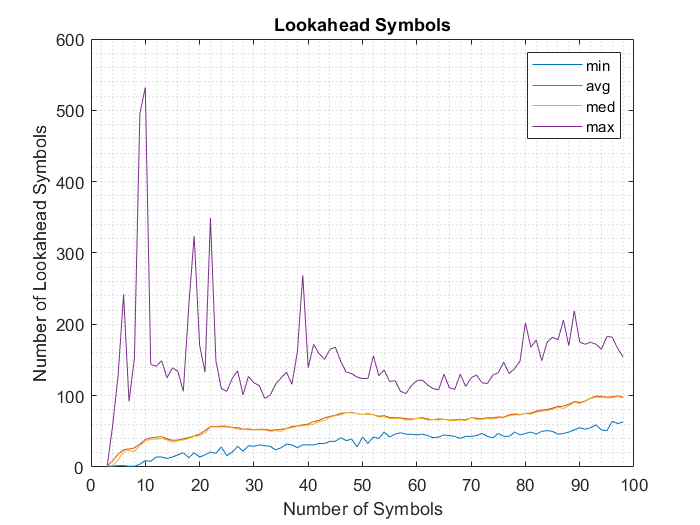

% Plot Number of Lookahead Symbols
for k= 1:4
    plot(results(:,1),results(:,5+k));
    hold on;
end
hold off;
legend("min","avg","med","max");
title("Lookahead Symbols");
xlabel("Number of Symbols");
ylabel("Number of Lookahead Symbols");
grid("minor");
%saveas(gcf,"lookahead_symbols.png"); 

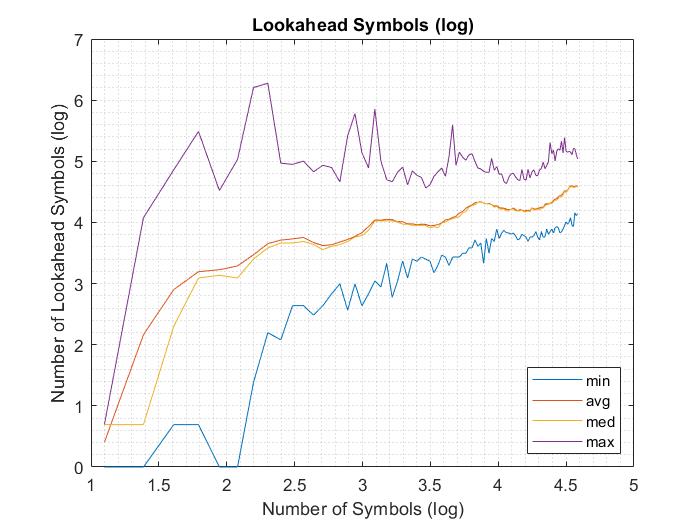

% Plot Number of Lookahead Symbols (log)
for k= 1:4
    plot(log(results(:,1)),log(results(:,5+k)));
    hold on;
end
hold off;
legend("min","avg","med","max","Location","southeast");
title("Lookahead Symbols (log)");
xlabel("Number of Symbols (log)");
ylabel("Number of Lookahead Symbols (log)");
grid("minor");
%saveas(gcf,"lookahead_symbols_log.png"); 

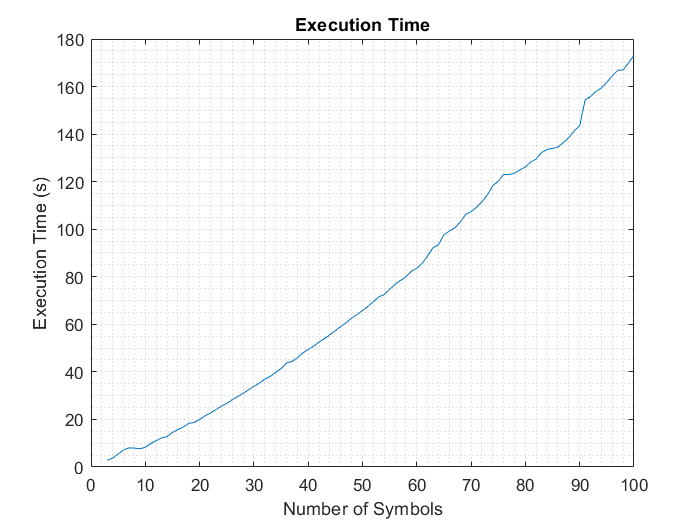

% Plot Execution Time
plot(times(:,1),times(:,2));
title("Execution Time");
xlabel("Number of Symbols");
ylabel("Execution Time (s)");
grid("minor");
%saveas(gcf,"execution_time.png"); 

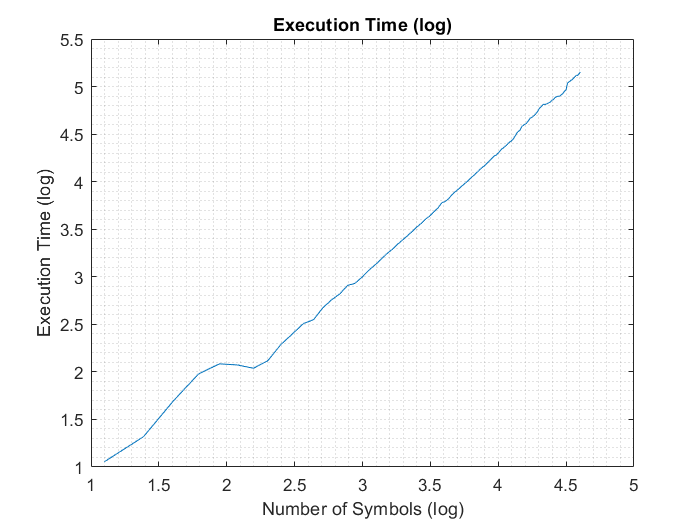

% Plot Execution Time (log)
plot(log(times(:,1)),log(times(:,2)));
title("Execution Time (log)");
xlabel("Number of Symbols (log)");
ylabel("Execution Time (log)");
grid("minor");
%saveas(gcf,"execution_time_log.png"); 

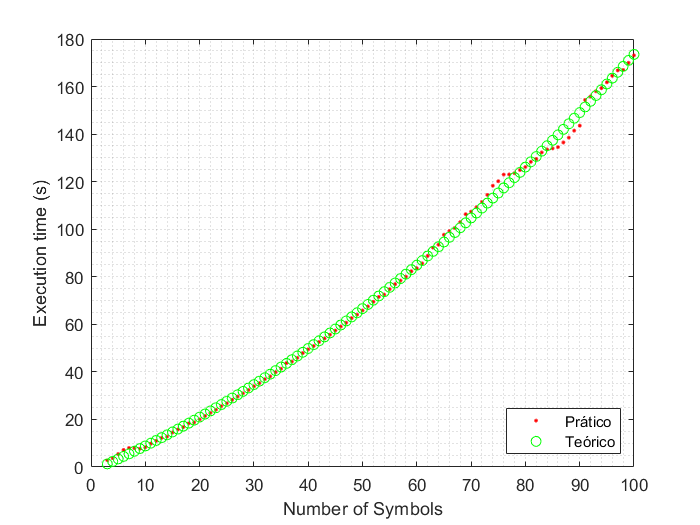

% Complexidade Computacional
x = times(:,1);                                                     % extract the first column
y = times(:,2);                                                     % extract the second column
X = [ x.^2, x, 0*x+1 ];                                             % build the X matrix for y(x) = Ax^2 + Bx + C 
w = pinv(X)*y;                                                      % optimal solution (could also be written as w = X \ y;)
e = y-X*w;                                                          % optional: compute the errors vector
format long;
w;                                                                  % print w --- A = w(1), B = w(2), and C = w(3)
norm(e);                                                            % optional: print the norm of the error vector (square root of the sum of squares)
plot(x,y,'.r',x,X*w,'og');                                          % plot the original data and its best least squares approximation
grid("minor");
xlabel("Number of Symbols");
ylabel("Execution time (s)");
legend("Prático","Teórico","Location","southeast");
%saveas(gcf,"c_complexity.png"); 

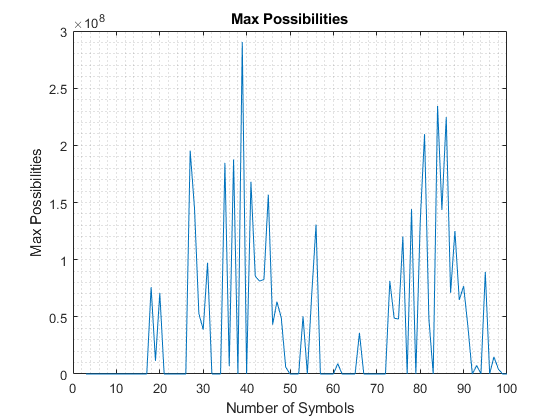

% Plot Max Possibilities
plot([3:100],maxp);
title("Max Possibilities");
xlabel("Number of Symbols");
ylabel("Max Possibilities");
grid("minor");
%saveas(gcf,"max_possibilities.png");